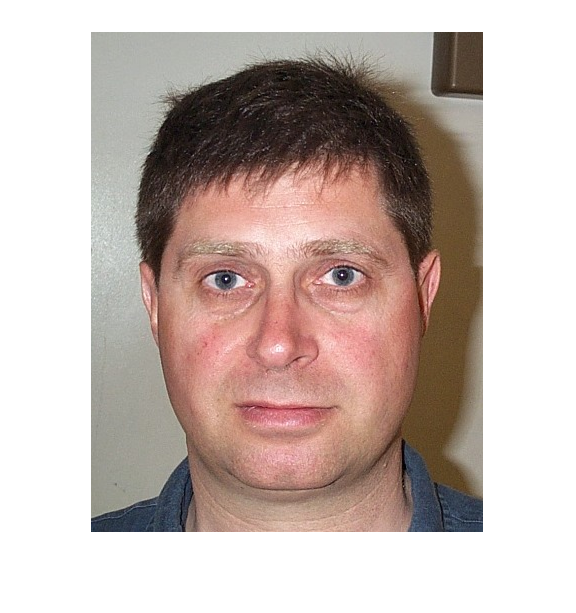

clear
I = imread('images\DB1\db1_01.jpg');

I = im2double(I);
imshow(I);

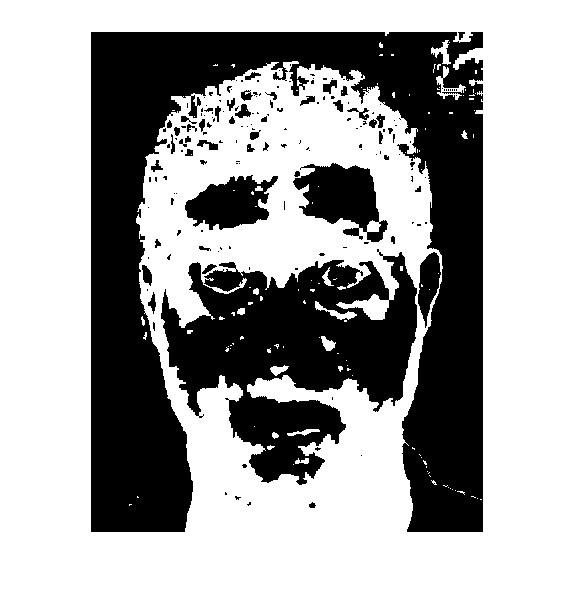


a=rgb2ycbcr(I);
[hue, ~,~] = rgb2hsv(I);
cb = a(:,:,2);
cr = a(:,:,3);

[w h]=size(I(:,:,1));

for i=1:w
    for j=1:h            
        if  0.5<=cr(i,j) && cr(i,j)<=0.6 && 0.4<=cb(i,j) && cb(i,j)<=0.5 && 0<=hue(i,j) && hue(i,j)<=0.075 %|| hue(i,j)>= 0.65    
            segment(i,j)=1;            
        else       
            segment(i,j)=0;    
        end    
    end
end

imshow(segment);

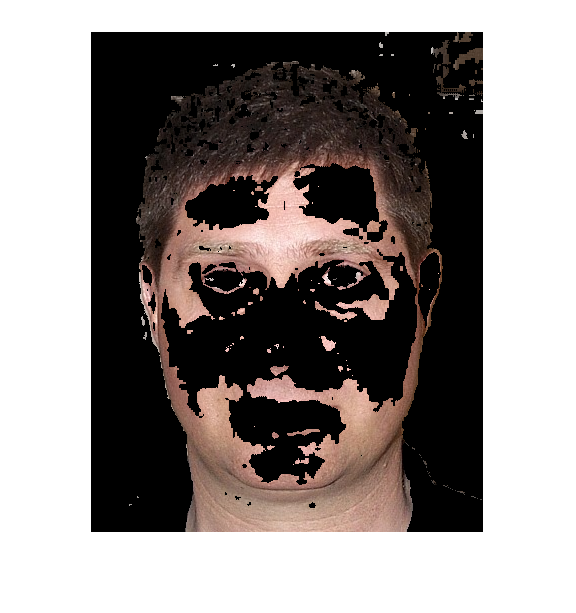


im(:,:,1)=I(:,:,1).*segment;   
im(:,:,2)=I(:,:,2).*segment; 
im(:,:,3)=I(:,:,3).*segment; 
figure,imshow((mat2gray(im)));






%returnimage = Segmentation(im);